# Dekodowanie DTMF

[s, fs] = audioread('lab06/s1.wav');


Recznie:

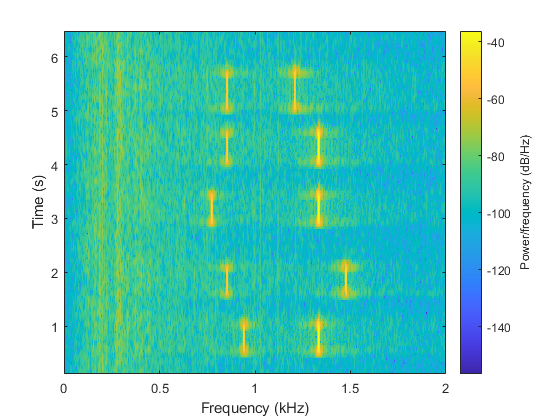

figure
spectrogram(s, 4096, 4096-512, [0:5:2000], fs);

importbutter()

f       = 0:fs-1;
%f       = linspace(0,fs,fs)
omega   = f*2*pi;

[b,a] = zp2tf(z,p,k); % z pierwiastkow na wielomian
[ha,wa]= freqs(b,a,omega);
% fvtool(b,a)

[bx,ax] = bilinear(b,a,fs);

[Hx,Wx] = freqz(bx,ax,fs,fs);
Xsig = fft(s);
Ya = Hx .* Xsig;

Matrix dimensions must agree.

yy = real(ifft(Ya));
m1 = max(s);
m2 = max(yy);
op = m1/m2;
yy = yy*op;
figure(2);
spectrogram(yy, 4096, 4096-512, [0:5:2000], fs);
figure
spectrogram(Ya, 4096, 4096-512, [0:5:2000], fs);